%load the images 
%noisy image is the 1-2 dose
%true image is the full dose

noise_info = dicominfo('//Client/C$/Users/toriwright/Downloads/Medical Imaging/SVD/Siemens Vision Quadra 17/Subject_136-141/09062022_1_20220609_163454/1-2 dose/09062022_1.PT.10.1.2022.06.09.17.13.50.366000.4.0.193503694.IMA');
i_noisy = dicomread(noise_info);
img_noisy = im2double(i_noisy)

img_noisy =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

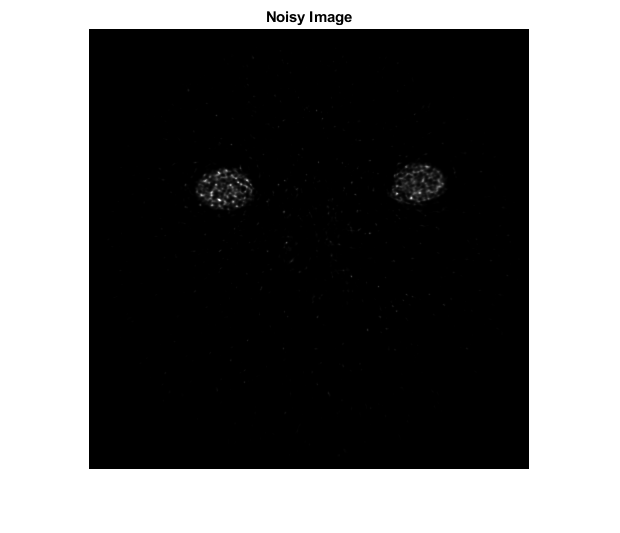

figure
imshow(abs(i_noisy), []);
title("Noisy Image");
saveas(gcf, "//Client/C$/Users/toriwright/Downloads/Medical Imaging/noisy.jpg", "jpg");


true_info = dicominfo('//Client/C$//Users/toriwright/Downloads/Medical Imaging/SVD/Siemens Vision Quadra 17/Subject_136-141/09062022_1_20220609_163454/Full_dose/09062022_1.PT.8.1.2022.06.09.18.13.45.205000.4.0.193193956.IMA');
i_true = dicomread(true_info);
img_true = im2double(i_true)

img_true =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

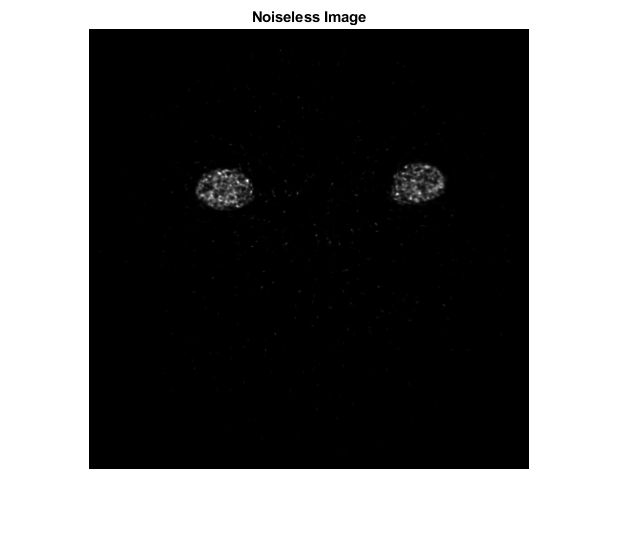

figure
imshow(abs(i_true),[]);
title("Noiseless Image");
saveas(gcf, "//Client/C$/Users/toriwright/Downloads/Medical Imaging/noiseless.jpg", "jpg");


if size(img_true) ~= size(img_noisy)
    disp("Noisy and the noiseless images don't match in dimension(s)");
end

SHAPE = size(img_true);
disp("Shape of the image is: ");

Shape of the image is: 


disp(SHAPE);

   440   440




%Compute the RRMSE between the noiseless and the noisy image:
error_baseline = rrmse(img_true, img_noisy); % This is the intial error. Any model that we design must be better than this.
fprintf("The RRMSE between the noisy and the noiseless image is: %.4f\n", error_baseline);

The RRMSE between the noisy and the noiseless image is: 0.5084



%Denoise
img_initial = img_noisy; % The initial "guess"
NOISE_MODEL = "complex_gaussian"; % Other option: "rician"

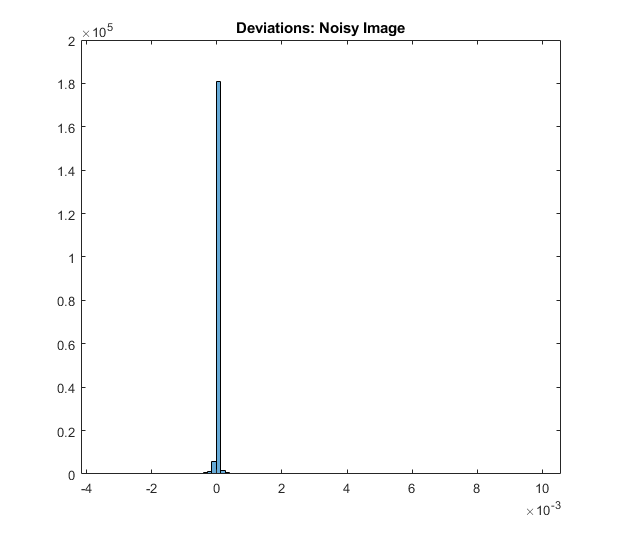


% Plotting the deviations:
temp = img_noisy - img_true;
temp = temp(:);
histogram(temp, 100);
title("Deviations: Noisy Image");


%Quadratic priors

% Optimal hyperparameters for Quadratic Penalty:
alpha_quad = 0.13;

sigma_quad = 1; % This is not tuned, since we tune alpha
N_iters_quad = 200;
lr_init_quad = 1e-4;

% Denoise and print the rrmse:
[img_denoised, obj_values] = adaptiveGradientDescent(img_noisy, img_initial, "quadratic", NOISE_MODEL, sigma_quad, alpha_quad, 0, N_iters_quad, lr_init_quad);

Feedback: Stopping at 128th iteration because step-size/learning-rate became too low


err_q = rrmse(img_true, img_denoised);
fprintf("The RRMSE for the Quadratic Prior with optimal parameters is: %.4f", err_q);

The RRMSE for the Quadratic Prior with optimal parameters is: 0.4409

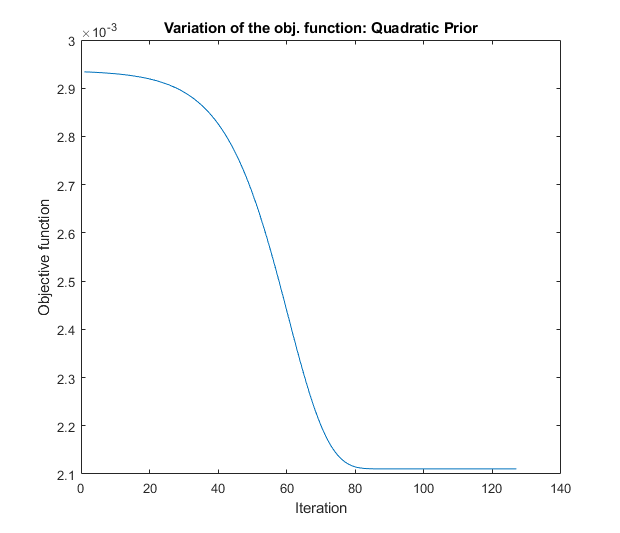


% Plot the objective function:
plot(1:size(obj_values), obj_values);
title("Variation of the obj. function: Quadratic Prior");
xlabel("Iteration");
ylabel("Objective function");
saveas(gcf, "//Client/C$/Users/toriwright/Downloads/Medical Imaging/obj_quadratic.jpg", "jpg");

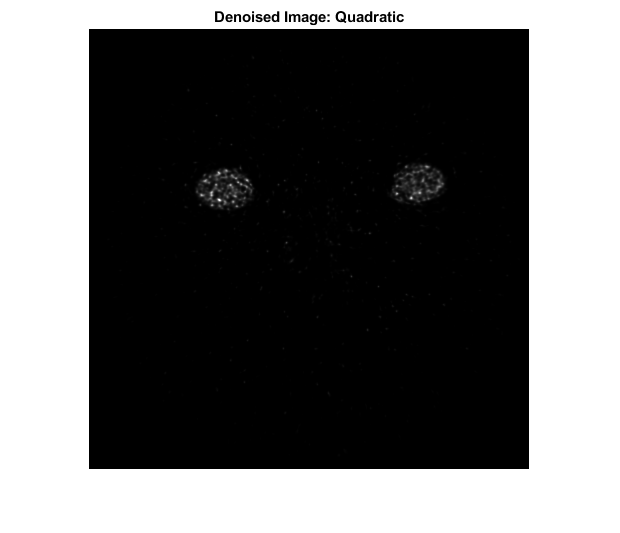



% Save the denoised image:
imshow(img_denoised, []);
title("Denoised Image: Quadratic");
saveas(gcf, "//Client/C$/Users/toriwright/Downloads/Medical Imaging/denoised_quadratic.jpg", "jpg");


% Reasoning for optimality of the hyperparameters: alpha
alpha_quad_1 = 0.8*alpha_quad;
alpha_quad_2 = min(1.2*alpha_quad, 1);

[img_denoised_1, ~] = adaptiveGradientDescent(img_noisy, img_initial, "quadratic", NOISE_MODEL, sigma_quad, alpha_quad_1, 0, N_iters_quad, lr_init_quad);

Feedback: Stopping at 126th iteration because step-size/learning-rate became too low


[img_denoised_2, ~] = adaptiveGradientDescent(img_noisy, img_initial, "quadratic", NOISE_MODEL, sigma_quad, alpha_quad_2, 0, N_iters_quad, lr_init_quad);

Feedback: Stopping at 127th iteration because step-size/learning-rate became too low



err_1 = rrmse(img_true, img_denoised_1);
err_2 = rrmse(img_true, img_denoised_2);

fprintf("The RRMSE for the Quadratic Prior at 0.8*alpha is: %.4f\n", err_1);

The RRMSE for the Quadratic Prior at 0.8*alpha is: 0.4523


fprintf("The RRMSE for the Quadratic Prior at 1.2*alpha is: %.4f", err_2);

The RRMSE for the Quadratic Prior at 1.2*alpha is: 0.4304



% Optimal hyperparameters:
alpha_huber = 0.54;
gamma_huber = 0.039;

sigma_huber = 1;
N_iters_huber = 200;
lr_init_huber = 1e-3;

[img_denoised, obj_values] = adaptiveGradientDescent(img_noisy, img_initial, "huber", NOISE_MODEL, sigma_huber, alpha_huber, gamma_huber, N_iters_huber, lr_init_huber);

Feedback: Stopping at 111th iteration because step-size/learning-rate became too low


err_h = rrmse(img_true, img_denoised);
fprintf("The RRMSE for the Huber Prior is: %.4f", err_h);

The RRMSE for the Huber Prior is: 0.3682

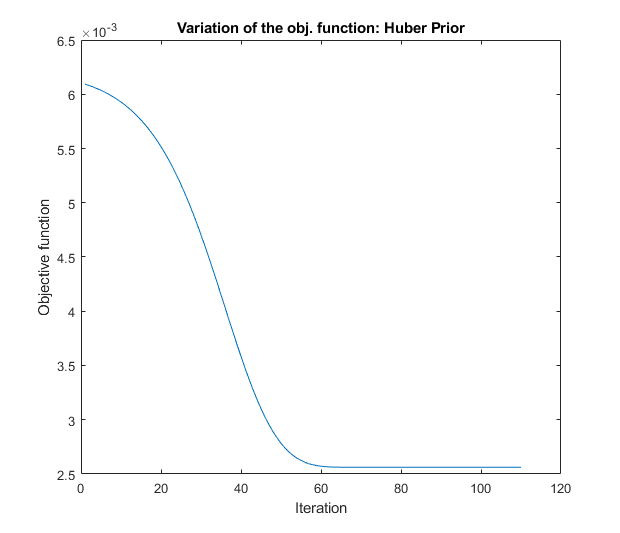


plot(1:size(obj_values), obj_values);
title("Variation of the obj. function: Huber Prior");
xlabel("Iteration");
ylabel("Objective function");
saveas(gcf, "//Client/C$/Users/toriwright/Downloads/Medical Imaging/obj_huber.jpg", "jpg");

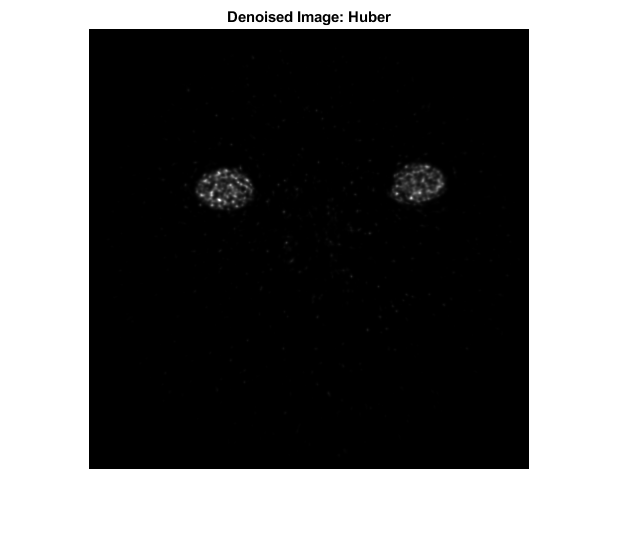


imshow(img_denoised,[]);
title("Denoised Image: Huber");
saveas(gcf, "//Client/C$/Users/toriwright/Downloads/Medical Imaging/denoised_huber.jpg", "jpg");


% Reasoning for optimality of the hyperparameter: alpha
alpha_huber_1 = 0.8*alpha_huber;
alpha_huber_2 = min(1.2*alpha_huber, 1);

[img_denoised_1, ~] = adaptiveGradientDescent(img_noisy, img_initial, "huber", NOISE_MODEL, sigma_huber, alpha_huber_1, gamma_huber, N_iters_huber, lr_init_huber);

Feedback: Stopping at 108th iteration because step-size/learning-rate became too low


[img_denoised_2, ~] = adaptiveGradientDescent(img_noisy, img_initial, "huber", NOISE_MODEL, sigma_huber, alpha_huber_2, gamma_huber, N_iters_huber, lr_init_huber);

Feedback: Stopping at 112th iteration because step-size/learning-rate became too low



err_1 = rrmse(img_true, img_denoised_1);
err_2 = rrmse(img_true, img_denoised_2);

fprintf("The RRMSE for the Huber Prior at 0.8*alpha is: %.4f\n", err_1);

The RRMSE for the Huber Prior at 0.8*alpha is: 0.3907


fprintf("The RRMSE for the Huber Prior at 1.2*alpha is: %.4f", err_2);

The RRMSE for the Huber Prior at 1.2*alpha is: 0.3512


% Reasoning for optimality of the hyperparameter: gamma
gamma_huber_1 = 0.8*gamma_huber;
gamma_huber_2 = 1.2*gamma_huber;

[img_denoised_1, ~] = adaptiveGradientDescent(img_noisy, img_initial, "huber", NOISE_MODEL, sigma_huber, alpha_huber, gamma_huber_1, N_iters_huber, lr_init_huber);

Feedback: Stopping at 111th iteration because step-size/learning-rate became too low


[img_denoised_2, ~] = adaptiveGradientDescent(img_noisy, img_initial, "huber", NOISE_MODEL, sigma_huber, alpha_huber, gamma_huber_2, N_iters_huber, lr_init_huber);

Feedback: Stopping at 111th iteration because step-size/learning-rate became too low



err_1 = rrmse(img_true, img_denoised_1);
err_2 = rrmse(img_true, img_denoised_2);

fprintf("The RRMSE for the Huber Prior at 0.8*gamma is: %.4f\n", err_1);

The RRMSE for the Huber Prior at 0.8*gamma is: 0.3682


fprintf("The RRMSE for the Huber Prior at 1.2*gamma is: %.4f", err_2);

The RRMSE for the Huber Prior at 1.2*gamma is: 0.3682



% Optimal hyperparameters:
alpha_daf = 0.91;
gamma_daf = 0.0045;

sigma_daf = 1;
N_iters_daf = 200;
lr_init_daf = 1e-3;

[img_denoised, obj_values] = adaptiveGradientDescent(img_noisy, img_initial, "daf", NOISE_MODEL, sigma_daf, alpha_daf, gamma_daf, N_iters_daf, lr_init_daf);

Feedback: Stopping at 108th iteration because step-size/learning-rate became too low


err_d = rrmse(img_true, img_denoised);
fprintf("The RRMSE for the DAF Prior is: %.4f", err_d);

The RRMSE for the DAF Prior is: 0.3764

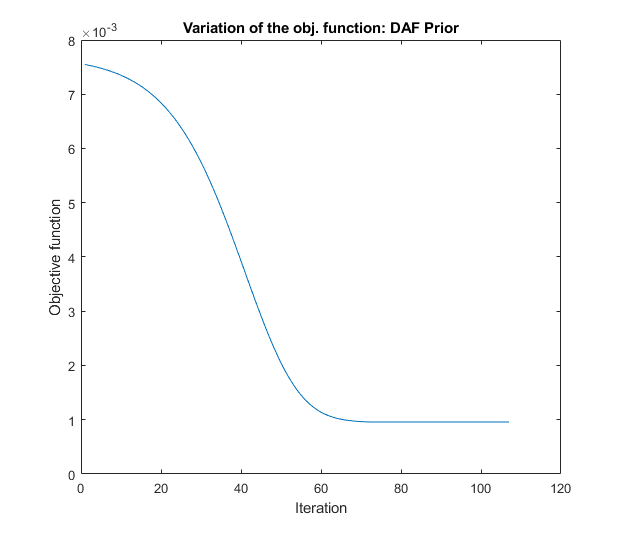

plot(1:size(obj_values), obj_values);
title("Variation of the obj. function: DAF Prior");
xlabel("Iteration");
ylabel("Objective function");
saveas(gcf, "//Client/C$/Users/toriwright/Downloads/Medical Imaging/obj_daf.jpg", "jpg");

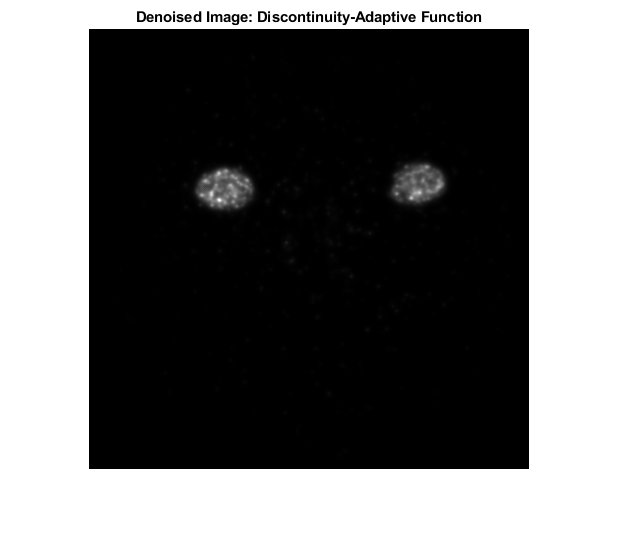


imshow(abs(img_denoised),[]);
title("Denoised Image: Discontinuity-Adaptive Function");
saveas(gcf, "//Client/C$/Users/toriwright/Downloads/Medical Imaging/denoised_daf.jpg", "jpg");


% Reasoning for optimality of the hyperparameter: alpha
alpha_daf_1 = 0.8*alpha_daf;
alpha_daf_2 = min(1.2*alpha_daf, 1);

[img_denoised_1, ~] = adaptiveGradientDescent(img_noisy, img_initial, "daf", NOISE_MODEL, sigma_daf, alpha_daf_1, gamma_daf, N_iters_daf, lr_init_daf);

Feedback: Stopping at 110th iteration because step-size/learning-rate became too low


[img_denoised_2, ~] = adaptiveGradientDescent(img_noisy, img_initial, "daf", NOISE_MODEL, sigma_daf, alpha_daf_2, gamma_daf, N_iters_daf, lr_init_daf);

Feedback: Stopping at 106th iteration because step-size/learning-rate became too low



err_1 = rrmse(img_true, img_denoised_1);
err_2 = rrmse(img_true, img_denoised_2);

fprintf("The RRMSE for the DAF Prior at 0.8*alpha is: %.4f\n", err_1);

The RRMSE for the DAF Prior at 0.8*alpha is: 0.3482


fprintf("The RRMSE for the DAF Prior at 1.2*alpha is: %.4f", err_2);

The RRMSE for the DAF Prior at 1.2*alpha is: 0.4655


% Reasoning for optimality of the hyperparameter: gamma
gamma_daf_1 = 0.8*gamma_daf;
gamma_daf_2 = 1.2*gamma_daf;

[img_denoised_1, ~] = adaptiveGradientDescent(img_noisy, img_initial, "daf", NOISE_MODEL, sigma_daf, alpha_daf, gamma_daf_1, N_iters_daf, lr_init_daf);

Feedback: Stopping at 108th iteration because step-size/learning-rate became too low


[img_denoised_2, ~] = adaptiveGradientDescent(img_noisy, img_initial, "daf", NOISE_MODEL, sigma_daf, alpha_daf, gamma_daf_2, N_iters_daf, lr_init_daf);

Feedback: Stopping at 108th iteration because step-size/learning-rate became too low



err_1 = rrmse(img_true, img_denoised_1);
err_2 = rrmse(img_true, img_denoised_2);

fprintf("The RRMSE for the DAF Prior at 0.8*gamma is: %.4f\n", err_1);

The RRMSE for the DAF Prior at 0.8*gamma is: 0.3753


fprintf("The RRMSE for the DAF Prior at 1.2*gamma is: %.4f", err_2);

The RRMSE for the DAF Prior at 1.2*gamma is: 0.3773